[[1711.03528] Quantum many-body scars](https://arxiv.org/abs/1711.03528)

[多体动力学演化python入门——quantum many-body scars 和稀疏矩阵后续 - 知乎](https://zhuanlan.zhihu.com/p/133462069)

% 参数设置
L = 12;

% Pauli 矩阵
sigma_x = sparse([0 1; 1 0]);
sigma_z = sparse([1 0; 0 -1]);
matrix_p = sparse([0 0; 0 1]);

% 构造单点算符
function op = op_onsite(index, op_single, L)
    op = 1;
    for i = 1:L
        if i == index
            op = kron(op, op_single);
        else
            op = kron(op, speye(2));
        end
    end
end

% 构造PXP哈密顿量的一个项（周期性边界条件）
function mat = matrix_PXP_PBC(index, L, matrix_p, sigma_x)
    idx1 = mod(index, L) + 1;
    idx2 = mod(index+1, L) + 1;
    idx3 = mod(index+2, L) + 1;
    mat = op_onsite(idx1, matrix_p, L) * ...
          op_onsite(idx2, sigma_x, L) * ...
          op_onsite(idx3, matrix_p, L);
end

% 构造总哈密顿量
Hamilton = sparse(2^L, 2^L);
for i = 1:L
    Hamilton = Hamilton + matrix_PXP_PBC(i, L, matrix_p, sigma_x);
end

% 初始态
state0 = sparse([1; 0]);
state1 = sparse([0; 1]);
state01 = kron(state0, state1);

% 构造观测算符
state_z2 = speye(1);
for i = 1:L/2
    state_z2 = kron(state_z2, state01);
end

i = L/2;
ob = op_onsite(i, sigma_z, L) * op_onsite(i+1, sigma_z, L);

% 演化与观测
function res = observations(ham, ob, state, start, endv, delta)
    tlist = start:delta:endv;
    res = zeros(size(tlist));
    state_t = expm(-1i*ham*start) * state;
    tran = expm(-1i*ham*delta);
    for idx = 1:length(tlist)
        res(idx) = (state_t' * ob * state_t);
        state_t = tran * state_t;
    end
end

start = 0;
endv = 25;
delta = 0.1;
res = observations(Hamilton, ob, state_z2, start, endv, delta);

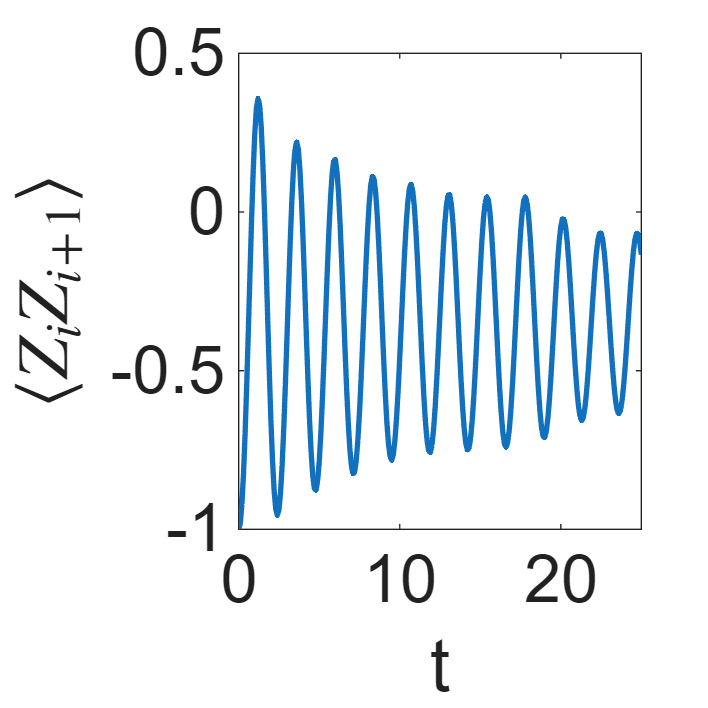


% 绘图
figure;
plot(start:delta:endv, real(res), 'LineWidth', 2);
xlabel('t', 'FontSize', fs);
ylabel('$\langle Z_i Z_{i+1}\rangle$', 'Interpreter','latex');
xlim([0, 25]);
set(gca, 'FontSize', fs);